clear all
load datos3

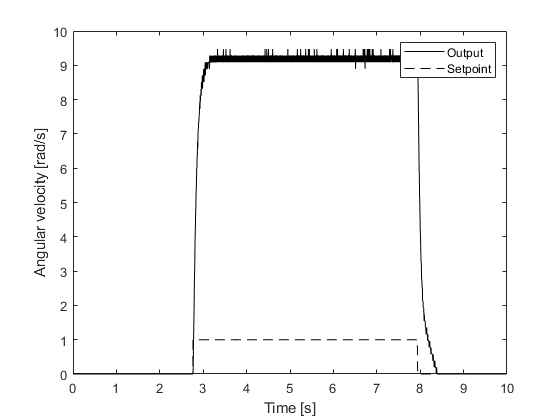

% graficar curva obtenida encendido/apagado del motor
plot(X_Value,ControlOutput,'k')
hold on
plot(X_Value,Setpoint,'--k')
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
legend('Output','Setpoint')
hold off


% tomando los datos de la curva de encendido
A=find(Setpoint==1,1); %encuentra indice del primer 1
A1=A*0.005   %ese indice por el la separacion

A1 = 2.7700


rangodatos=2.77/0.005:3.355/0.005;
aux1=X_Value(rangodatos)-X_Value(rangodatos(1));
aux2=ControlOutput(rangodatos);
% grafica
plot(aux1,aux2,'xk')
hold on
plot(aux1,Setpoint(rangodatos),'--k')

% obteniendo función de transferencia por el método
% de Smith
K=mean(aux2(0.4/0.005:end)); % promedio de los ultimos valores
[a11,i11]=min(abs(aux2-0.635*K))  %busca el indice de 63.5%

a11 = 0.1698

i11 = 18

% Tao=0.15-0.07;
Tao = aux1(i11); % indice 63.5% en tiempo


fun=tf([K],[Tao,1])


fun =
 
     9.174
  -----------
  0.085 s + 1
 
Continuous-time transfer function.



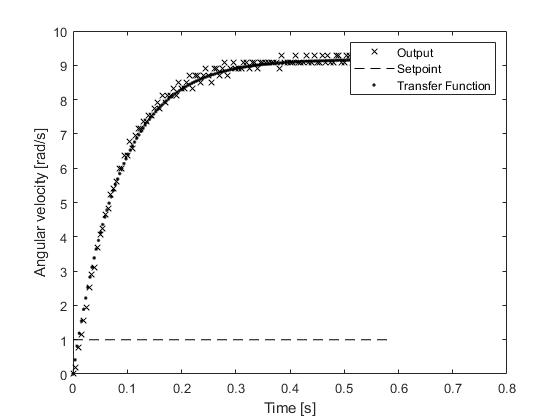

hold on
[yAux,xAux]=step(fun);
stairs(xAux,yAux,'.k')
legend('Output','Setpoint','Transfer Function')
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')


wc=10/Tao;
T=0.005;
filtro=tf(1,[1/wc,1])


filtro =
 
       1
  ------------
  0.0085 s + 1
 
Continuous-time transfer function.



filtrodigital = c2d(filtro,T)


filtrodigital =
 
    0.4447
  ----------
  z - 0.5553
 
Sample time: 0.005 seconds
Discrete-time transfer function.




numfiltrodigital=filtrodigital.num{1};
denfiltrodigital=filtrodigital.den{1};
% tranfzcurva = ztrans(aux2)


% probando integral
hold off

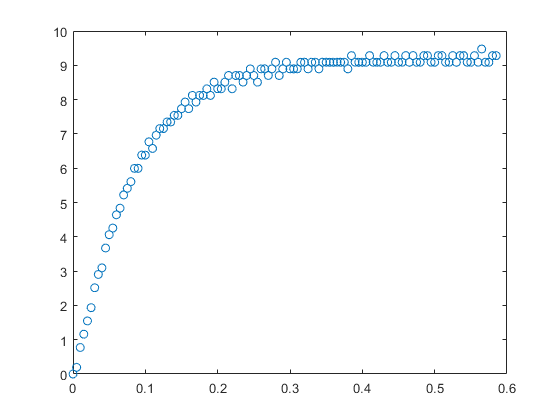

plot(aux1,aux2,'o')

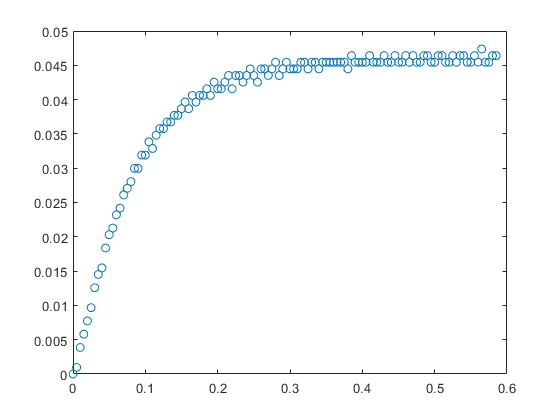

aux2aux=aux2*0.005;
plot(aux1,aux2aux,'o')

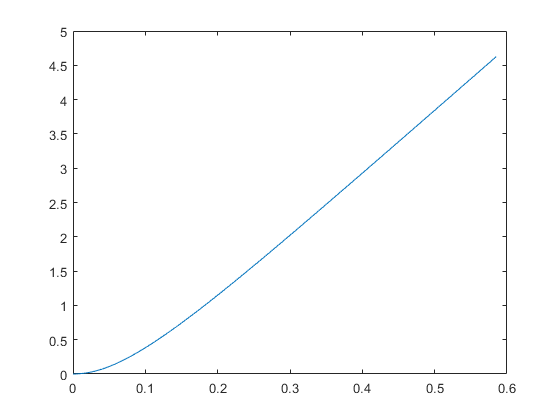

for i = 1:length(aux2)
    auxdiaux(i)=sum(aux2aux(1:i));
end
plot(aux1,auxdiaux)

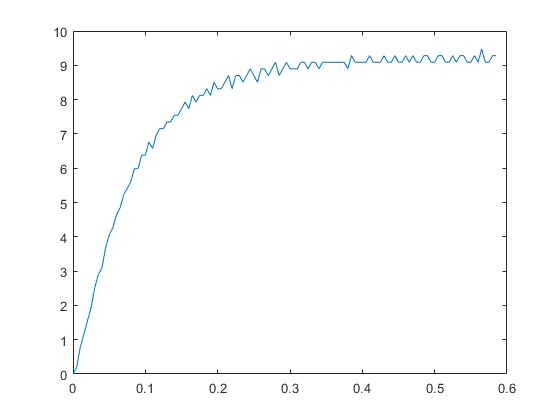


AA=[0,auxdiaux(1:end-1)];
AAA=(auxdiaux-AA)./0.005;
plot(aux1,AAA)

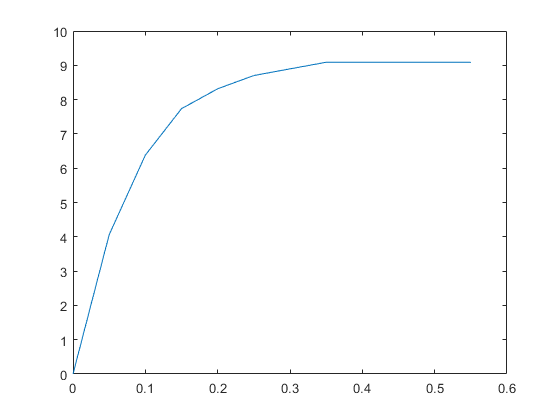

plot(aux1(1:10:end),aux2(1:10:end))

aplicando el filtro

ecuacion en diferencias

y_k=x_k-1+b*y_k-1

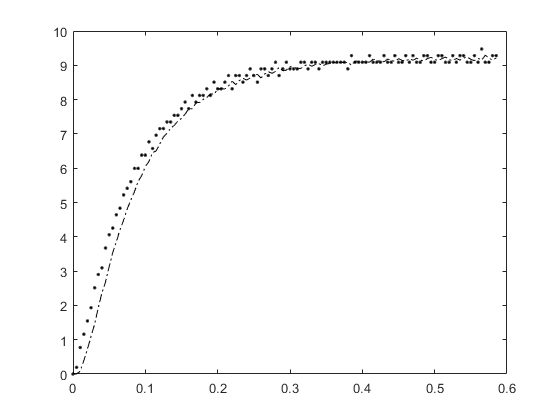

y=[0];
for i=2:length(aux2) %para y valor actual comienza en 2
    y(i)=numfiltrodigital(1,end)*aux2(i-1)-denfiltrodigital(1,end)*y(i-1);
end
plot(aux1,y,'-.k')
hold on
plot(aux1,aux2,'.k')  % al aplicar el filtro se agrega un retardo

según la formula de zoh

z=tf('z',0.005)


z =
 
  z
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Funcionzoh = K*(1-1/z)*z*(1-exp(-(1/Tao)*T))/((z-1)*(z-exp(-(1/Tao)*T)))


Funcionzoh =
 
    0.5241 z^2 - 0.5241 z
  --------------------------
  z^3 - 1.943 z^2 + 0.9429 z
 
Sample time: 0.005 seconds
Discrete-time transfer function.



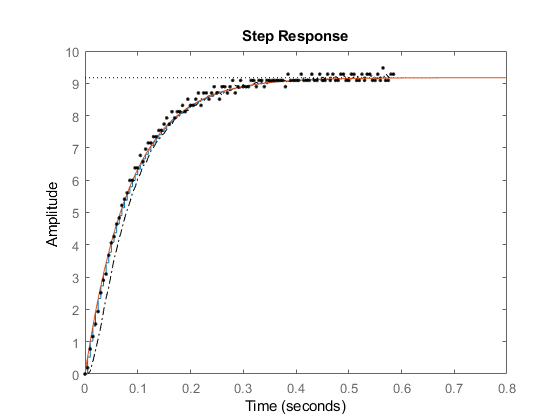

step(Funcionzoh)
step(fun)